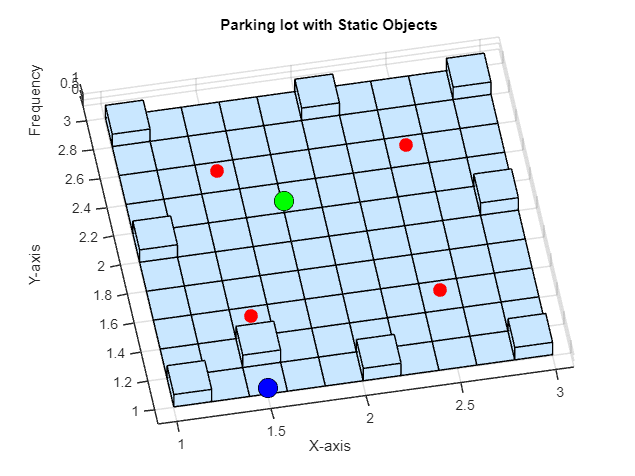

x = [1 1; 1 2; 1 3; 2 1; 1.5 1.25; 2 3; 3 1; 3 2; 3 3];
hist3(x);

% Set up the axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Frequency');
title('Parking lot with Static Objects');

% Define positions for static objects
staticObjects = [1.5 1.5 0.5; 2.5 2.5 0.5; 1.5 2.5 0.5; 2.5 1.5 0.5]; % Add more objects as needed

% Define positions for anchors (LOS and NLOS)
LOS_anchor = [1.8, 2.2, 1.0];  % LOS anchor
NLOS_anchor = [1.5, 1, 0.5]; % NLOS anchor

% Plot static objects
hold on;
scatter3(staticObjects(:, 1), staticObjects(:, 2), staticObjects(:, 3), 100, 'filled', 'MarkerFaceColor', 'r');

% Plot anchors
scatter3(LOS_anchor(1), LOS_anchor(2), LOS_anchor(3), 200, 'filled', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'k'); % LOS anchor
scatter3(NLOS_anchor(1), NLOS_anchor(2), NLOS_anchor(3), 200, 'filled', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'k'); % NLOS anchor

hold off;